## ***Solución Punto 1***

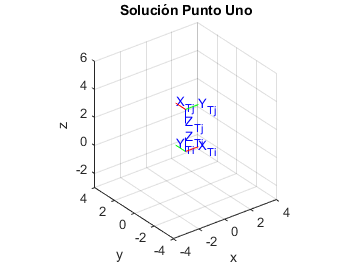

plotvol([-4 4 -4 4 -3 6]);
T0 = eye(4);

T1 = [0 1 0  0;
      1 0 0  0;
      0 0 -1 3;
      0 0 0  1];

trplot(T0, 'frame', 'Ti', 'rgb');
tranimate(T0,T1,'frame','Tj','rgb')
title("Solución Punto Uno")

## ***Ejemplo 1***

% ATB = transl(6,-2,10)*trotx(90)
Trasla = [1 0 0 6;
          0 1 0 -2;
          0 0 1 10;
          0 0 0 1]

Trasla =      1     0     0     6
     0     1     0    -2
     0     0     1    10
     0     0     0     1


Trot =   [1 0 0 0;
          0 cosd(90) -sind(90) 0;
          0 sind(90)  cosd(90) 0;
          0 0 0 1]

Trot =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


ATB = Trasla*Trot

ATB =      1     0     0     6
     0     0    -1    -2
     0     1     0    10
     0     0     0     1


## ***Solución Punto 2***

% equation= Trotx(alpha)*Traslx(b)*Traslz(d)*Trotz(teta)
syms alpha b d teta
equation = trotx(alpha)*transl(b,0,0)*transl(0,0,d)*trotz(teta)

$$equation = \left(\begin{array}{cccc} \cos\left(\mathrm{teta}\right) & -\sin\left(\mathrm{teta}\right) & 0 & b\\ \cos\left(\alpha \right)\,\sin\left(\mathrm{teta}\right) & \cos\left(\alpha \right)\,\cos\left(\mathrm{teta}\right) & -\sin\left(\alpha \right) & -d\,\sin\left(\alpha \right)\\ \sin\left(\alpha \right)\,\sin\left(\mathrm{teta}\right) & \sin\left(\alpha \right)\,\cos\left(\mathrm{teta}\right) & \cos\left(\alpha \right) & d\,\cos\left(\alpha \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## ***Solución Punto 3***

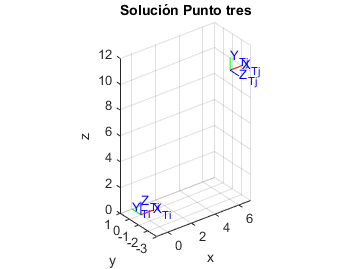

plotvol([-1 7 -3 1 0 12]);
T0 = eye(4);

T1 = [ 1 0 0    6;
       0 0 -1  -2 ;
       0 1  0  10;
       0 0 0    1];

trplot(T0, 'frame', 'Ti', 'rgb');
tranimate(T0,T1,'frame','Tj','rgb')

title("Solución Punto tres")

## ***Ejemplo de Punto 4 a.***

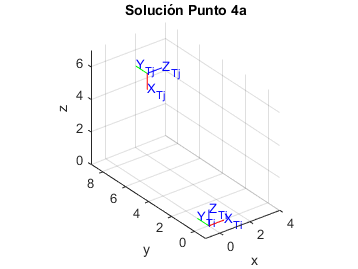


plotvol([-1 4 -1 9 0 7]);
T0 = eye(4);

T1 = [0 0 1 2;
      0 1 0  8 ;
      -1 0 0 5;
      0 0 0 1];

trplot(T0, 'frame', 'Ti', 'rgb');
tranimate(T0,T1,'frame','Tj','rgb')
title("Solución Punto 4a")

## ***Ejemplo  de Punto 4 b.***

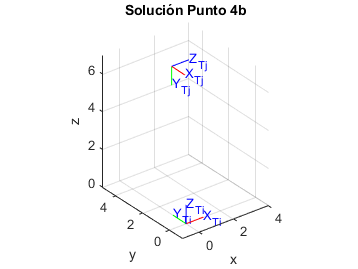

plotvol([-1 4 -1 5 0 7]);
T0 = eye(4);

T1 = [ 0  0  1  3;
      -1  0  0  5 ;
       0 -1  0  5;
       0  0  0  1];

trplot(T0, 'frame', 'Ti', 'rgb');
tranimate(T0,T1,'frame','Tj','rgb')
title("Solución Punto 4b")